%%1
t = 10;
num = randi([1, 5], 1, t);
prob_odd_count_10 = sum(mod(num,2))/t

prob_odd_count_10 = 0.8000


t = 50;
num = randi([1, 5], 1, t);
prob_odd_count_50 = sum(mod(num,2))/t

prob_odd_count_50 = 0.5600


t = 100;
num = randi([1, 5], 1, t);
prob_odd_count_100 = sum(mod(num,2))/t

prob_odd_count_100 = 0.6600


t = 500;
num = randi([1, 5], 1, t);
prob_odd_count_500 = sum(mod(num,2))/t

prob_odd_count_500 = 0.6020


t = 1000;
num = randi([1, 5], 1, t);
prob_odd_count_1000 = sum(mod(num,2))/t

prob_odd_count_1000 = 0.5910


%1,3,5
math_analy_prob_odd = 3/5

math_analy_prob_odd = 0.6000


%d
P = [2/7, 2/7, 1/7, 1/7, 1/7];

t = 10;
outcomes = randsample(1:5, t, true, P);
d_prob_odd_count_10 = sum(mod(outcomes,2))/t

d_prob_odd_count_10 = 0.9000


t = 50;
outcomes = randsample(1:5, t, true, P);
d_prob_odd_count_50 = sum(mod(outcomes,2))/t

d_prob_odd_count_50 = 0.5200


t = 100;
outcomes = randsample(1:5, t, true, P);
d_prob_odd_count_100 = sum(mod(outcomes,2))/t

d_prob_odd_count_100 = 0.5000


t = 500;
outcomes = randsample(1:5, t, true, P);
d_prob_odd_count_500 = sum(mod(outcomes,2))/t

d_prob_odd_count_500 = 0.5780


t = 1000;
outcomes = randsample(1:5, t, true, P);
d_prob_odd_count_1000 = sum(mod(outcomes,2))/t

d_prob_odd_count_1000 = 0.5480


%P = [2/7, 2/7, 1/7, 1/7, 1/7];
% 1,2,3
d_math_analy_prob_odd = (2+1+1)/7

d_math_analy_prob_odd = 0.5714

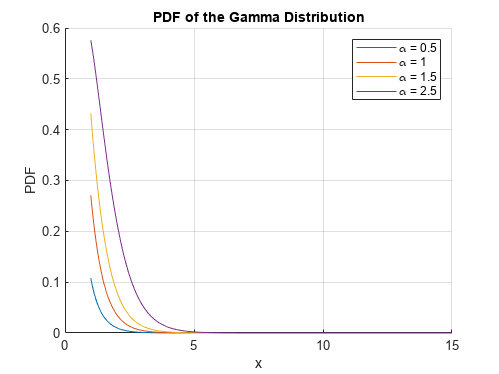

%%2
x = linspace(1, 15, 1000);
figure;
hold on;
title('PDF of the Gamma Distribution');
xlabel('x');
ylabel('PDF');
grid on;

lambda = 0.5;
alpha_values = [0.5, 1, 1.5, 2.5];


alpha = alpha_values(1);
pdf = gampdf(x, alpha, lambda); % Compute PDF
plot(x, pdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(2);
pdf = gampdf(x, alpha, lambda); % Compute PDF
plot(x, pdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(3);
pdf = gampdf(x, alpha, lambda); % Compute PDF
plot(x, pdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(4);
pdf = gampdf(x, alpha, lambda); % Compute PDF
plot(x, pdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
legend show;
hold off;

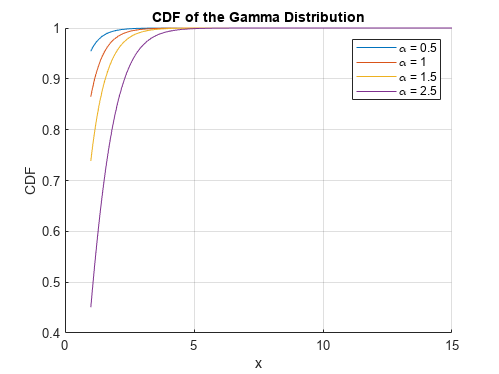


figure;
hold on;
title('CDF of the Gamma Distribution');
xlabel('x');
ylabel('CDF');
grid on;
alpha = alpha_values(1);
cdf = gamcdf(x, alpha, lambda); % Compute CDF
plot(x, cdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(2);
cdf = gamcdf(x, alpha, lambda); % Compute CDF
plot(x, cdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(3);
cdf = gamcdf(x, alpha, lambda); % Compute CDF
plot(x, cdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(4);
cdf = gamcdf(x, alpha, lambda); % Compute CDF
plot(x, cdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
legend show;
hold off;


%c
t = 100

t = 100

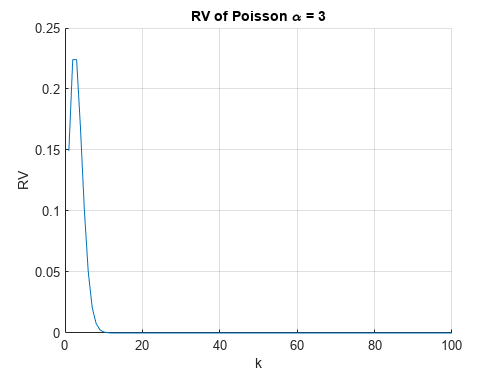

k = linspace(1, t, t);
alpha_values = [3, 25, 100];

figure;
hold on;
title('RV of Poisson \alpha = 3');
xlabel('k');
ylabel('RV');
grid on;
alpha = alpha_values(1);
Poisson_RV = (alpha.^k).*exp(-alpha)./factorial(k);
plot(k, Poisson_RV, 'DisplayName', ['\alpha = ', num2str(alpha)]);
hold off;

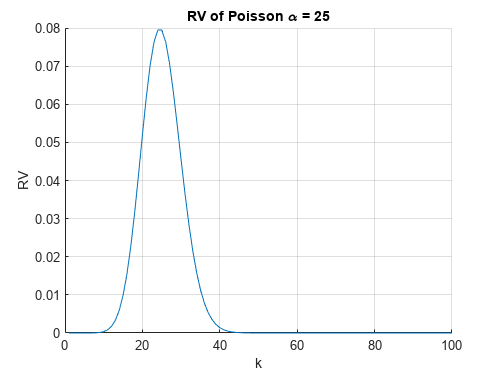


figure;
hold on;
title('RV of Poisson \alpha = 25');
xlabel('k');
ylabel('RV');
grid on;
alpha = alpha_values(2);
Poisson_RV = (alpha.^k).*exp(-alpha)./factorial(k);
plot(k, Poisson_RV, 'DisplayName', ['\alpha = ', num2str(alpha)]);
hold off;

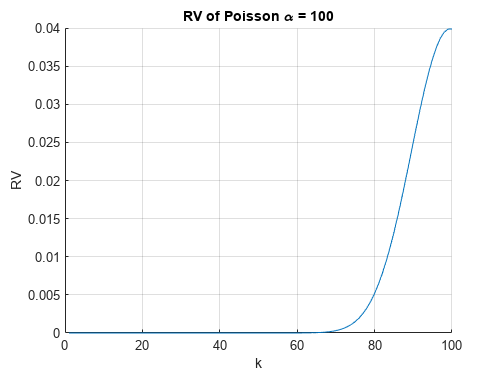


figure;
hold on;
title('RV of Poisson \alpha = 100');
xlabel('k');
ylabel('RV');
grid on;
alpha = alpha_values(3);
Poisson_RV = (alpha.^k).*exp(-alpha)./factorial(k);
plot(k, Poisson_RV, 'DisplayName', ['\alpha = ', num2str(alpha)]);
hold off;

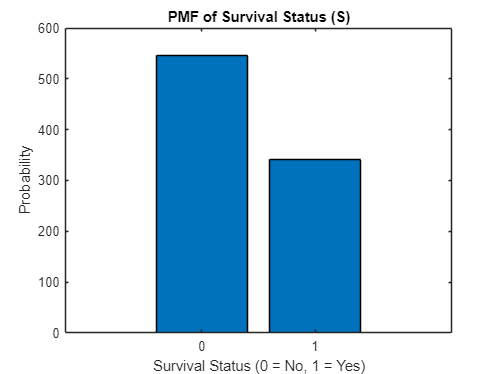

%3
data = readtable('modified_titanic.xlsx');
S = data.Survived;
C = data.Pclass;
G = data.Sex;
A = data.Age;

n=887;

pmf_S = histcounts(S);
figure;
x = 0:1:1;
bar(x,pmf_S);
title('PMF of Survival Status (S)');
xlabel('Survival Status (0 = No, 1 = Yes)');
ylabel('Probability');

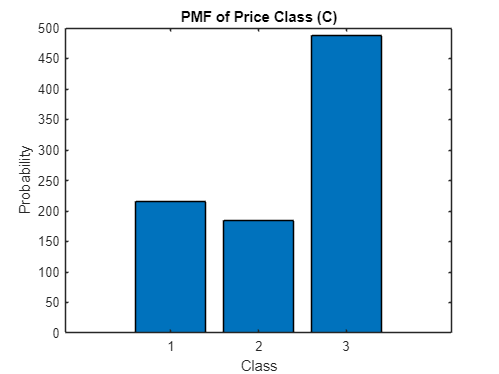


pmf_C = histcounts(C);
figure;
bar(pmf_C);
x = 1:3:3;
title('PMF of Price Class (C)');
xlabel('Class');
ylabel('Probability');

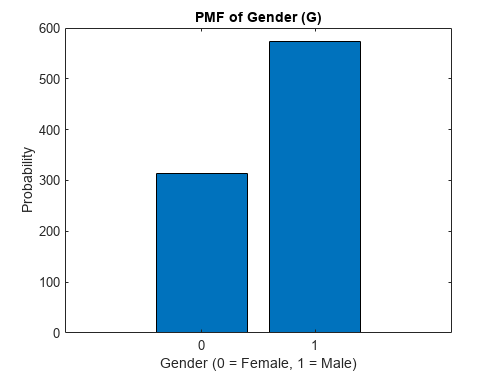


pmf_G = histcounts(G);
figure;
x = 0:1:1;
bar(x,pmf_G);
title('PMF of Gender (G)');
xlabel('Gender (0 = Female, 1 = Male)');
ylabel('Probability');

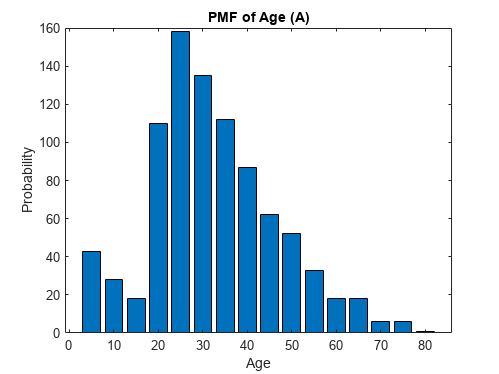


[pmf_A,edges] = histcounts(A);
figure;
bar(edges(2:length(edges)),pmf_A);
title('PMF of Age (A)');
xlabel('Age');
ylabel('Probability');


%Survived
SCount = 0;
for i = 1:n
    if data.Survived(i) == 1
        SCount = SCount + 1;
    end
end
P_SCount = SCount/n

P_SCount = 0.3856


PClass1_Count=0;
for i = 1:n
    if data.Survived(i) == 1 && data.Pclass(i) == 1
        PClass1_Count = PClass1_Count + 1;
    end
end
P_PClass1_Count = PClass1_Count/SCount

P_PClass1_Count = 0.3977


PClass2_Count=0;
for i = 1:n
    if data.Survived(i) == 1 && data.Pclass(i) == 2
        PClass2_Count = PClass2_Count + 1;
    end
end
P_PClass2_Count = PClass2_Count/SCount

P_PClass2_Count = 0.2544


PClass3_Count=0;
for i = 1:n
    if data.Survived(i) == 1 && data.Pclass(i) == 3
        PClass3_Count = PClass3_Count + 1;
    end
end
P_PClass3_Count = PClass3_Count/SCount

P_PClass3_Count = 0.3480


GCount=0;
for i = 1:n
    if data.Survived(i) == 1 && data.Sex(i) == 0
        GCount = GCount + 1;
    end
end
P_GCount_female = GCount/SCount

P_GCount_female = 0.6813


GCount=0;
for i = 1:n
    if data.Survived(i) == 1 && data.Sex(i) == 1
        GCount = GCount + 1;
    end
end
P_GCount_male = GCount/SCount

P_GCount_male = 0.3187